# Figure S1G

**Load Data**

clear
[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = '..\..\FINAL DATA files\';
%imagePath = '';
%%% Experiment Paremeters %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

load([dataDir filesep 'A060_data.mat'],'S','settings','allIF');

conditions = settings.conditions;
framesPerHr = 60/12;
 frameDrugAdded =0;
frameEdU = 0;
timeStart = 0;

folding =5;

numFrames = size(S(1).area,2);
xFrames = 1:numFrames;
xTime = (xFrames-1)./framesPerHr;



times = arrayfun(@(x)(numFrames - x.POI)/framesPerHr,S,'UniformOutput',false);
[S.POI_time] = times{:};
% 
for i = 1:length(S)
    S(i).frameDrugAdded = conditions{i,5};
    S(i).POI_realtime = S(i).POI/framesPerHr;
    S(i).POI_drug_time = ( S(i).frameDrugAdded - S(i).POI)/framesPerHr;
   S(i).drug_time = S(i).frameDrugAdded/framesPerHr;
end

 drug_time = frameDrugAdded/framesPerHr;

**Gate cells**

for i = 1:length(S)
    dat = S(i);
    apcExpressGate = false(length(dat.POI(:,1)),1);
    apcGate = false(length(dat.POI(:,1)),1);
    apcGateAll = false(length(dat.POI(:,1)),1);
    cdkHighGate = false(length(dat.POI(:,1)),1);
crlGate = false(length(dat.POI(:,3)),1);

    for n = 1:length(dat.POI(:,1))
        if dat.POI(n,1) > 1 * framesPerHr & dat.POI(n,1) < numFrames - 1 * framesPerHr
            apcExpressGate(n) = nanmean(dat.apcAreaNormM(n,dat.POI(n,1) + [-1* framesPerHr: -.5* framesPerHr] )) > .5 & ...
                nanmean(dat.apcAreaNormM(n,dat.POI(n,1) + [round(.5* framesPerHr): 1* framesPerHr] )) < .1;
        end
        %more permissive gating for MCF10A cells
        if dat.POI(n,1) + round(10*framesPerHr) <= numFrames 
            apcGate(n) = dat.apcNormM(n,dat.POI(n,1) + round(10*framesPerHr)) < .02;
            apcGateAll(n) = ~isnan(dat.apcNormM(n,dat.POI(n,1) + round(10*framesPerHr)));
        end
        if dat.POI(n,1) + round(6*framesPerHr) <= numFrames 
            cdkHighGate(n) = dat.cdk(n,dat.POI(n,1) + round(6*framesPerHr)) > .7;
        end
        if dat.POI(n,3) + round(4*framesPerHr) <= numFrames 
            crlGate(n) = dat.crlNormAct(n,dat.POI(n,3) + round(4* framesPerHr)) < .5 ;
        end

    end
    S(i).apcExpressGate = apcExpressGate;
    S(i).apcGate = apcGate;
    S(i).apcGateAll = apcGateAll;
%     S(i).cdkGate = cdkGate;
   S(i).crlGate = crlGate;
        S(i).cdkHighGate = cdkHighGate;

end

CRL activation post mitosis

conds=[1 6];
timeGate = [0 20];
cols =  [0 0 .5;.4 .7 0;.941 .447 .282;.333 .302 .541; 1 .831 0;  .855 .384 .49; .647 .22 .376; .271 .035 .125; .525 .075 .788; .075 .322 .702];;

figure('unit','inches','position',[0 0 4 8])
nexttile
hold on
POI_align = 1;
POI_cal = 3;
data_out = [];
frames_out = [];

for i=1:length(conds)
    data = S(conds(i));
      inds = ~isnan(S(conds(i)).POI(:,POI_align)) &  ...
        S(conds(i)).POI_realtime(:,1) <= timeGate(2) & S(conds(i)).POI_realtime(:,1) >= timeGate(1) & S(conds(i)).goodCdk & S(conds(i)).apcExpressGate ;
    if conds(i) == 8
        inds = inds & S(conds(i)).apcGate;
    else
        inds = inds & S(conds(i)).apcGateAll;
    end


    mat = NaN * ones(size(data.area));
    event = data.POI(:,POI_cal);

    start = data.POI(:,POI_align);
    ends = data.traceStats(:,6);

     y = event- start ;
    lost = ends  - start ;
    y = y/framesPerHr; %y = time of POI_cal relative to POI_align
    lost = lost/framesPerHr; % lost = last frame relative to POI_align
    censor = isnan(y); %if y isnan, censor = 1
    y(censor) = lost(censor);
    y_filt = y(inds);
    censor_filt = censor(inds);
    [f,x] = ecdf(y_filt,'Censoring',censor_filt);
    if isempty(f)
        f = 0;
        x = 0;
    end
    y_max = max(y_filt(censor_filt));
    if x(end) < y_max
        x(end+1) = y_max;
        f(end + 1) = f(end);
    end
    if f(end) == 1
        x(end+1) = 1000;
        f(end + 1) = f(end);
    end
     if x(1) ~= 0
        x0 = 0;
        f0 = 0;
        f = cat(1,f0,f);
        x = cat(1,x0,x);
     end 

    plot(x,f,'Color',cols(i,:),'linewidth',2);
 
    sum(inds)
end

ans = 985

ans = 767



axis square
set(gca,'fontsize',16,'linewidth',2)
legend('Control','siEmi1','Box','off','Location','north','FontSize',18);
xlim([0 15]); 
xticks(0:5:20)
ylim([0 1]);
xlabel('Time after mitosis (h)')
ylabel('Proportion of cells entered S phase')
hold on

APC inactivation post mitosis


nexttile

hold on
POI_align = 1;
POI_cal = 2;
data_out = [];
frames_out = [];

for i=1:length(conds)
    data = S(conds(i));
    
       inds = ~isnan(S(conds(i)).POI(:,POI_align)) &  ...
        S(conds(i)).POI_realtime(:,1) <= timeGate(2) & S(conds(i)).POI_realtime(:,1) >= timeGate(1) & S(conds(i)).goodCdk & S(conds(i)).apcExpressGate ;
    if conds(i) == 8
        inds = inds & S(conds(i)).apcGate;
    else
        inds = inds & S(conds(i)).apcGateAll;
    end

 mat = NaN * ones(size(data.area));
    event = data.POI(:,POI_cal);

    start = data.POI(:,POI_align);
    ends = data.traceStats(:,6);

     y = event- start ;
    lost = ends  - start ;
    y = y/framesPerHr; %y = time of POI_cal relative to POI_align
    lost = lost/framesPerHr; % lost = last frame relative to POI_align
    censor = isnan(y); %if y isnan, censor = 1
    y(censor) = lost(censor);
    y_filt = y(inds);
    censor_filt = censor(inds);
    [f,x] = ecdf(y_filt,'Censoring',censor_filt);
    if isempty(f)
        f = 0;
        x = 0;
    end
    y_max = max(y_filt(censor_filt));
    if x(end) < y_max
        x(end+1) = y_max;
        f(end + 1) = f(end);
    end
    if f(end) == 1
        x(end+1) = 1000;
        f(end + 1) = f(end);
    end
     if x(1) ~= 0
        x0 = 0;
        f0 = 0;
        f = cat(1,f0,f);
        x = cat(1,x0,x);
     end 


    plot(x,f,'Color',cols(i,:),'linewidth',2);
    sum(inds) 
end

ans = 985

ans = 767

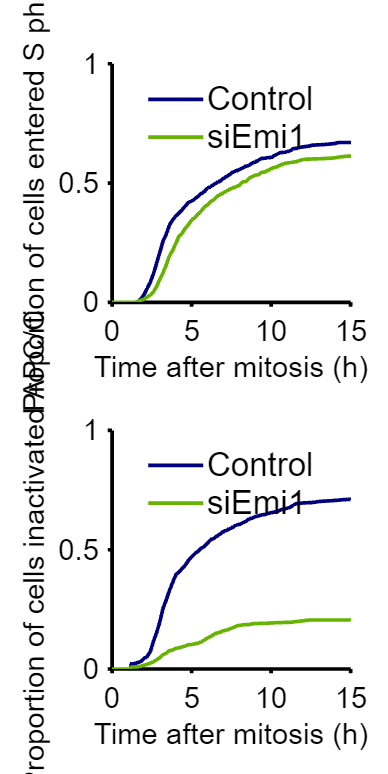



axis square
set(gca,'fontsize',16,'linewidth',2)
legend('Control','siEmi1','Box','off','Location','north','FontSize',18);
xlim([0 15]); 
xticks(0:5:20)
ylim([0 1]);
xlabel('Time after mitosis (h)')
ylabel('Proportion of cells inactivated APC/C')

% print_pdf(['fig_1_mcf10A_emi1kd.pdf'])
